Defining a system symbolically.

syms s K;
gain = K;
feedback = 1;
plant = 1/(s*(s+1)*(s+2));     % Open-loop.
sys = gain * plant + feedback; % Closed-loop.

Characteristic equation representation of the system.

coeffs = ELAB.sd2ce(sys, true);

Original expression:


$$\frac{K}{s\,\left(s+1\right)\,\left(s+2\right)}+1$$

Expanded form:


$$\frac{K}{s^{3}+3\,s^{2}+2\,s}+1$$

Set equal to 0, then simplify:


$$s^{3}+3\,s^{2}+2\,s+K$$

Collect terms of equal power:


$$s^{3}+3\,s^{2}+2\,s+K$$

Routh array for stability analysis.

RA = ELAB.routh(coeffs, true);

Routh Array


$$\left(\begin{array}{cc} 1 & 2\\ 3 & K\\ 2-\frac{K}{3} & 0\\ K & 0 \end{array}\right)$$

Critical points, where system transitions between stable and unstable.

ELAB.critical(RA,true);

Solving equations for param:


$$2-\frac{K}{3}=0$$

$$K=0$$

For stability, param (K) = ]6;0[

From s^2 auxiliary equation:


$$\left(\begin{array}{cc} 3\,s^{2}+6=0 & 3\,s^{2}=0 \end{array}\right)$$

Solved for s:


$$\left(\begin{array}{cc} -\sqrt{2}\,\mathrm{i} & 0\\ \sqrt{2}\,\mathrm{i} & 0 \end{array}\right)$$

Breakaway points for root locus plot.

ELAB.breakaway(sys, gain, true);

Solving closed-loop for gain:


$$K=-s\,\left(s+1\right)\,\left(s+2\right)$$

Expanding expression:


$$K=-s^{3}-3\,s^{2}-2\,s$$

Derivative of gain of s:


$$-3\,s^{2}-6\,s-2$$

Solving diff(gain) = 0 for s:


$$\left(\begin{array}{cc} s=-\frac{\sqrt{3}}{3}-1 & s=\frac{\sqrt{3}}{3}-1 \end{array}\right)$$

Sub s in 1st equation, solving for gain.
Breakaway points [s, gain]:
   -1.5774   -0.3849
   -0.4226    0.3849



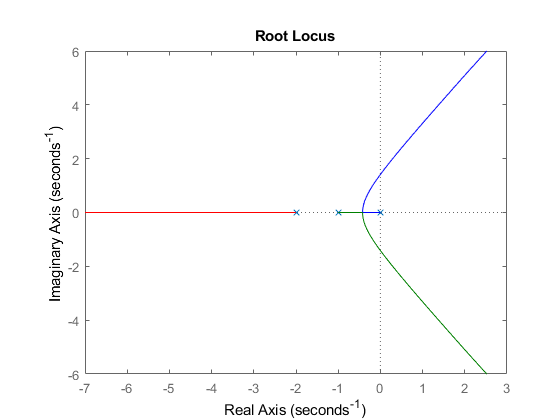

plant = ELAB.sd2tf(plant); % Convert symbolic to tf-object for rlocus.
rlocus(plant);